# Problem 4

Write a `MATLAB` funcion, called `bisection_method` that takes as inputs a function $f$, two numbers $a$, $b$, an error tolerance, `tol`, and a maximum number of iterations, $N$, and finds a root $c$ of $f$ in the interval $[a , b]$ using the bisection method. Your function should compute a bound on the error, and stop when the error is less than the tolerance, or if the number of iterations exceeds $N$ - whichever happens first.

clc; close all; clear variables;

function [c, iter, err] = bisection_method(f, a, b, tol, N)
    % make sure a, b, and tol are floats
    if ~isnumeric(a) || ~isnumeric(b) || ~isnumeric(tol)
        fprintf('a, b, and tol must be numbers');
        return;
    end

    % make sure N is a natural number
    if ~isnumeric(N) || N < 1 || mod(N, 1) ~= 0
        fprintf('N must be a natural number.');
        return;
    end

    % make sure f(x) is callable
    if ~isa(f, 'function_handle')
        fprintf('f(x) must be callable (e.g., a function)');
        return;
    end

    % make sure bisection method is applicable
    if f(a) * f(b) > 0
        return;
    end

    % start iterating
    err = (b - a) / 2;
    for i = 1:N
        % start evaluating at the halfway point
        c = (a + b) / 2;

        % if we're in the tolerance range, exit the function
        if err < tol
            iter = i;
            return;
        end

        % if f(c) == 0, we found an exact root
        if f(c) == 0
            iter = i;
            return;
        end

        % otherwise, narrow the search range
        if f(a) * f(c) < 0
            b = c;
        else
            a = c;
        end
        err = (b - a) / 2;
    end

    % if we exceeded maximum iterations, just return what we 
    % found
    % if I were putting this in some larger code base, I would 
    % probably include whether we exceeded the maximum
    % iterations in the return value, since the function might
    % get used in a way such that the user can't be expected to
    % look at the terminal
    % ---------------------------------------------------------
    fprintf('Maximum iterations exceeded.');
    iter = i;
    return;
end

f = @(x) x^2 - 2*x - 3;
bisection_method(f, 0, 5, 10^-5, 3)

Maximum iterations exceeded.

ans = 3.1250

## Problem 4(c)

f = @(x) (2*x.^3 + 3.*x - 1).*cos(x) - x

f = function_handle with value:
    @(x)(2*x.^3+3.*x-1).*cos(x)-x


a = -1;
b = 1;
tol = 10^-5;
[root, iterations, error] = bisection_method(f, a, b, tol, 100)

root = 0.4386

iterations = 18

error = 7.6294e-06

### Problem 4(c.iv)

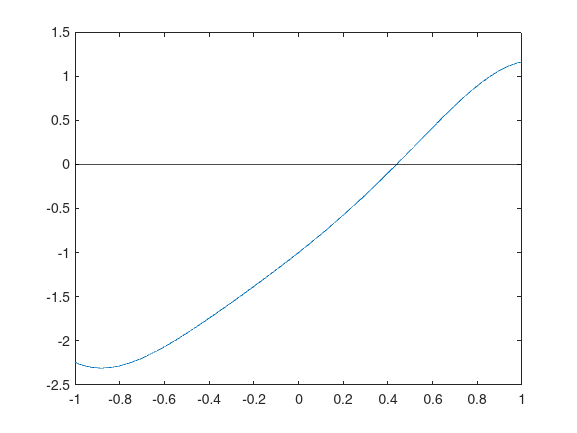

xs = linspace(-1, 1, 400);
y = f(xs);
figure;
plot(xs, y);
hold on;
yline(0, "Color", "black", "LineWidth", 0.5);
hold off;

### 4(c.v)

interval = [ -1 , 1];
root = fzero (f , interval )

root = 0.4386

# Problem 5

Write a `MATLAB` function, called `fixed_point_method` that takes as inputs a function, $g$, an initial guess $x_0$, an error tolerance, `tol`, and a maximum number of iterations, $N$, and outputs the fixed point of g, obtained using the fixed point method, starting with $x_0$. Your function should have an error defined by $E = |x_n - x_{n-1}|$, which is the absolute difference between the last two iterations, and stop when that error is less than the tolerance, or if the number of iterations exceeds $N$ - whichever happens first. Your function header should look something like:

`function [c, n, err] = fixed_point_method(g, x0, tol, N)`

function [c, iter, err] = fixed_point_method(g, x_0, tol, N)
    if ~isa(g, 'function_handle')
        disp('g(x) must be callable (e.g., a function).');
        return;
    end
    if ~isnumeric(x_0) || ~isnumeric(tol)
        disp('x_0 and tol must be numbers.');
        return;
    end
    if ~isnumeric(N) || N < 1 || mod(N, 1) ~= 0
        disp('N must be a natural number.');
        return;
    end
    for i = 1:N
        disp(x_0);
        c = g(x_0);
        err = abs(c - x_0);
        if err < tol
            iter = i;
            return;
        end
        x_0 = c;
    end

    disp('Maximum iterations exceeded');
    iter = i;
    err = abs(c - x_0);
    return;
end

g = @(x) exp(x*-1);

[root, iterations, error] = fixed_point_method(g, 0, 10^-10, 100)

     0

     1

    0.3679

    0.6922

    0.5005

    0.6062

    0.5454

    0.5796

    0.5601

    0.5711

    0.5649

    0.5684

    0.5664

    0.5676

    0.5669

    0.5673

    0.5671

    0.5672

    0.5671

    0.5672

    0.5671

    0.5671

    0.5671

    0.5671

    0.5671

    0.5671

    0.5671

    0.5671

    0.5671

    0.5671

    0.5671

    0.5671

    0.5671

    0.5671

    0.5671

    0.5671

    0.5671

    0.5671

    0.5671

    0.5671

    0.5671

    0.5671



root = 0.5671

iterations = 42

error = 8.2180e-11

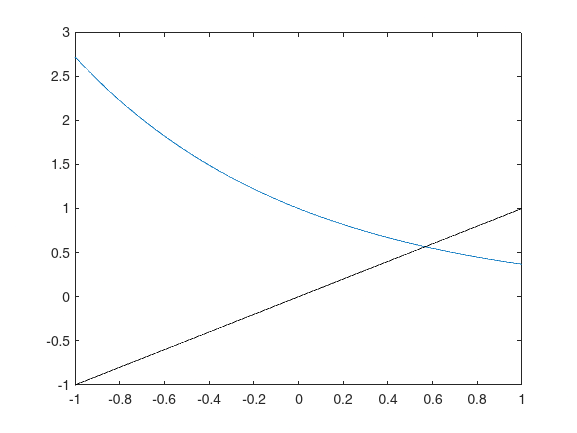


xs = linspace(-1, 1, 400);
y = g(xs);
figure;
plot(xs, y);
hold on;
line (xs, xs, Color="black", LineWidth=0.5)

# Problem 6

Write a `MATLAB` function, called `Newtons_method` that takes as inputs a function, $f$, its derivative, $f'$, an initial guess $x_0$, an error tolerance, `tol`, and a maximum number of iterations, $N$, and outputs the root of $f$ obtained using Newton's method (denoted by $c$). Your function should have an error defined by `err = |`$x_n - x_{n-1}$`|`, and stop when the error is less than the tolerance, or if the number of iterations exceeds $N$ - whichever happens first. Your function header should look something like:

`function [c, n, err] = Newtons_method(f, fp, x0, tol, N)`

Where `n` is the last iteration when you stop.

Use the function you created to find the root of the equation $arctan(x) = 1$ with an initial guess $x_0 = 2$, to an accuracy of less than $tol = 10^{-8}$. **(Written)** Did your method converge, and if so, how many iterations did it take? If not, why didn't it converge, and what happened-did it diverge, or end up in an infinite loop? Plot on the same graph the function and the axis $y = 0$. Test with $x_0 = -2$. What is happening?

function [c, iter, err] = newtons_method(f, fp, x_0, tol, n)
    for i = 1:n
        try
            f_prime = fp(x_0);
        catch ME
            if strcmp(ME.identifier, 'MATLAB:overflow')
                disp('Function diverges');
                c = Inf;
                iter = i;
                err = Inf;
                return;
            else
                disp(['Other error: ', ME.message]);
                return;
            end
        end

        c = x_0 - f(x_0) / f_prime;
        err = abs(c - x_0);

        if err < tol
            iter = i;
            return;
        end
        if f(c) == 0
            iter = i;
            return;
        end
        x_0 = c;
    end
    disp('Maximum iterations exceeded');
    iter = i;
    return;
end

f = @(x) atan(x) - 1;
fp = @(x)(1 / (x^2 + 1));
tol = 10^-8;
newtons_method(f, fp, 2, tol, 100)

ans = 1.5574

newtons_method(f, fp, -2, tol, 100)

Maximum iterations exceeded


ans = NaN

When finding the root of the equation $arctan(x) = 1$ using `Newtons_method` using $x_0 = -2$, the function runs into an overflow error. What happens is that the method diverges; the derivative at the initial point is shallow enough to cause it to choose a new point on the next iteration that is much farther away. Because with $arctan$, the derivative gets closer to $0$ as $x$ gets farther away, the distance from the starting point keeps increasing, getting further and further away from the origin until $x_n$ is too large to be represented in the computer's memory.

Choosing $x_0 = 2$ allows the function to converge because the derivative at that point is steep enough to send the next iteration to a point closer to zero, allowing the method to converge.